## Boas práticas

clc;                    % limpa a tela
clear all;              % limpa as variáveis
close all;              % fecha as figuras

## Declaração de Variáveis

syms t;
N = 10;
n = [-N:1:N];
Res = 1e-3;   
g1Tempo = [0:Res:1];       % vetor tempo 1
g2Tempo = [0:Res:1];       % vetor tempo 2
g3Tempo = [1:Res:2];       % vetor tempo 3

## Funções do Exercício

g1 = @(t) exp(-t);               % Função g1
g2 = @(t) exp(-10*t);            % Função g2
g3 = @(t) exp((-1)*(t-1));       % Função g3
gN = @(n,t) exp(-j*n*2*pi*t);

## 1- Cáculo das Potências

pg1 = potencia(g1(t),0,1)

pg1 = 0.4323

pg2 = potencia(g2(t),0,1)

pg2 = 0.0500

pg3 = potencia(g3(t),1,2)

pg3 = 0.4323

## 2- Cálculo do C

for k = 1:2*N+1 
clc;

cn1(k) = projecao(g1(t),gN(n(k),t),0,1);
cn2(k) = projecao(g2(t),gN(n(k),t),0,1);
cn3(k) = projecao(g3(t),gN(n(k),t),1,2);

end


## 3- Exibiçaõ de g

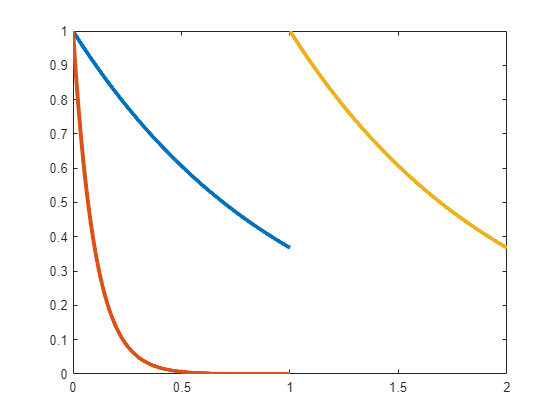

plot(g1Tempo,g1(g1Tempo)','LineWidth',3);
hold on
plot(g2Tempo,g2(g2Tempo)','LineWidth',3);
plot(g3Tempo,g3(g3Tempo)','LineWidth',3);
hold off

## 4- Exibição do C

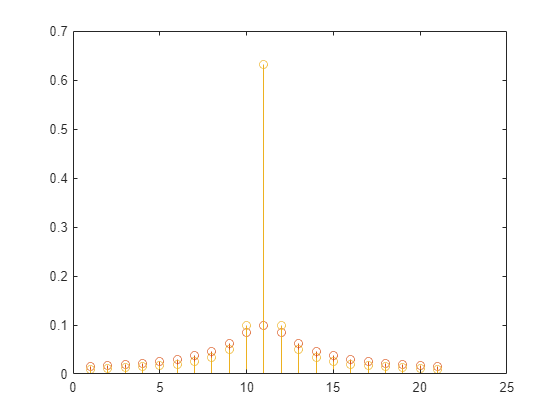

stem(abs(cn1));
hold on
stem(abs(cn2));
stem(abs(cn3));
hold off

## Relação dos Resultados 2, 3, 4 com 1

A partir das potências calculadas no tópico 1, é notável que as funções g1 e g3 possuem a mesma potência, devido que em seus respectivos intervalos, ambas possuem a mesma forma e amplitude.

O fenômemo apresentado em 4 também é evidenciado pelo mesmo motivo de seus valores serem iguais.